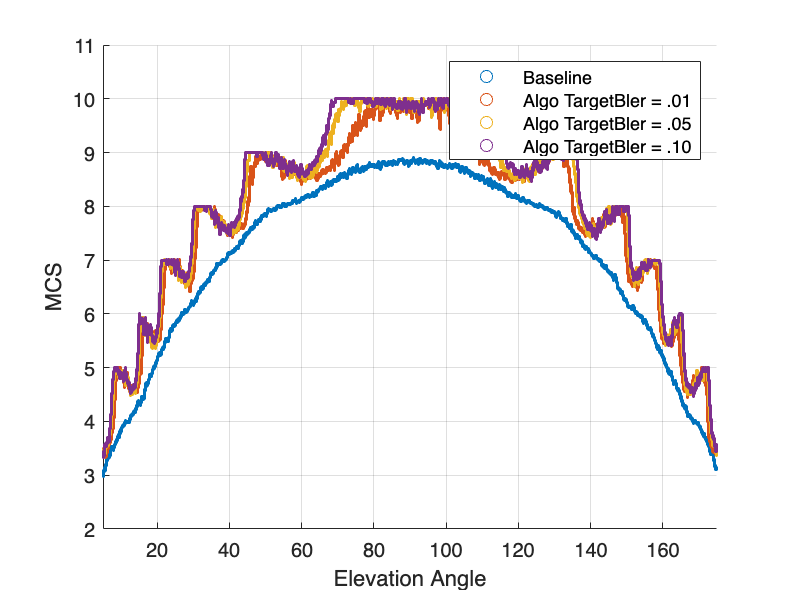

B05 = Case9MCSThroughputCalulationBLERw100Tbler05;
B10 = Case9MCSThroughputCalulationBLERw100Tbler10;
B01 = Case9MCSThroughputCalulationBLERw100Tbler01;
Base = Case9MCSThroughputCalulation240524212808;
% figure(1);clf;
% hold on
% grid on
% scatter(Base.eleAnge,Base.CUMSUM_BLKER,1)
% scatter(B01.eleAnge,B01.CUMSUM_BLKER,1)
% scatter(B05.eleAnge,B05.CUMSUM_BLKER,1)
% scatter(B10.eleAnge,B10.CUMSUM_BLKER,1)
% xlim([0 180])
% xlabel("Elevation Angle")
% ylabel("Cumulative BlockErrors")
% legend('Baseline','Algo TargetBler = .01','Algo TargetBler = .05','Algo TargetBler = .10')
% hold off


% figure(2);clf;
% hold on
% grid on
% nonZeroB01=(~B01.CUMSUM_Throughput==0);
% nonZeroB05=(~B05.CUMSUM_Throughput==0); 
% nonZeroB10=(~B10.CUMSUM_Throughput==0); 
% scatter(Base.eleAnge,Base.CUMSUM_Throughput,1)
% scatter(B01.eleAnge(nonZeroB01),B01.CUMSUM_Throughput(nonZeroB01),1)
% scatter(B05.eleAnge(nonZeroB05),B05.CUMSUM_Throughput(nonZeroB05),1)
% scatter(B10.eleAnge(nonZeroB10),B10.CUMSUM_Throughput(nonZeroB10),1)
% xlabel("Elevation Angle")
% ylabel("Cumulative Throughput")
% legend('Baseline','Algo TargetBler = .01','Algo TargetBler = .05','Algo TargetBler = .10')
% hold off

% figure(3);clf;
% hold on
% grid on
% lag = 10000;
% bAvgBLER = movavg(Base.BLER,'simple',lag);
% b01AvgBLER = movavg(B01.BLER,'simple',lag);
% b05AvgBLER = movavg(B05.BLER,'simple',lag);
% b10AvgBLER = movavg(B10.BLER,'simple',lag);
% scatter(Base.eleAnge,bAvgBLER,1)
% scatter(B01.eleAnge,b01AvgBLER,1)
% scatter(B05.eleAnge,b05AvgBLER,1)
% scatter(B10.eleAnge,b10AvgBLER,1)
% xlim([5 175])
% ylim([0 0.11])
% xlabel("Elevation Angle")
% ylabel("Block Error Rate")
% legend('Baseline','Algo TargetBler = .01','Algo TargetBler = .05','Algo TargetBler = .10')
% hold off

% figure(4);clf;
% hold on
% grid on
% lag = 1000;
% bAvg = movavg(Base.RATE,'simple',lag);
% b01Avg = movavg(B01.RATE,'simple',lag);
% b05Avg = movavg(B05.RATE,'simple',lag);
% b10Avg = movavg(B10.RATE,'simple',lag);
% % scatter(Base.eleAnge,Base.RATE,1)
% % scatter(B01.eleAnge,B01.RATE,1)
% % scatter(B05.eleAnge,B05.RATE,1)
% % scatter(B10.eleAnge,B10.RATE,1)
% scatter(Base.eleAnge,bAvg,1)
% scatter(B01.eleAnge,b01Avg,1)
% scatter(B05.eleAnge,b05Avg,1)
% scatter(B10.eleAnge,b10Avg,1)
% xlim([0 180])
% % ylim([0 0.11])
% xlabel("Elevation Angle")
% ylabel("Rate (bps)")
% legend('Baseline','Algo TargetBler = .01','Algo TargetBler = .05','Algo TargetBler = .10')
% hold off

figure(3);clf;
hold on
grid on
lag = 2000;
bAvgBLER = movavg(Base.MCS,'simple',lag);
b01AvgBLER = movavg(B01.MCS,'simple',lag);
b05AvgBLER = movavg(B05.MCS,'simple',lag);
b10AvgBLER = movavg(B10.MCS,'simple',lag);
scatter(Base.eleAnge,bAvgBLER,1)
scatter(B01.eleAnge,b01AvgBLER,1)
scatter(B05.eleAnge,b05AvgBLER,1)
scatter(B10.eleAnge,b10AvgBLER,1)
xlim([5 175])
% ylim([0 0.11])
xlabel("Elevation Angle")
ylabel("MCS")
legend('Baseline','Algo TargetBler = .01','Algo TargetBler = .05','Algo TargetBler = .10')
hold off